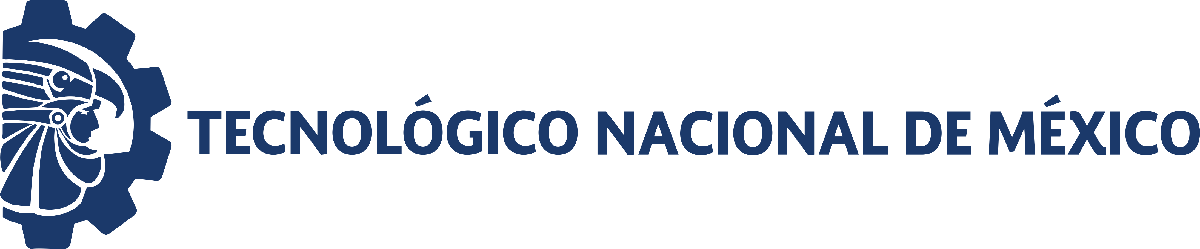                                 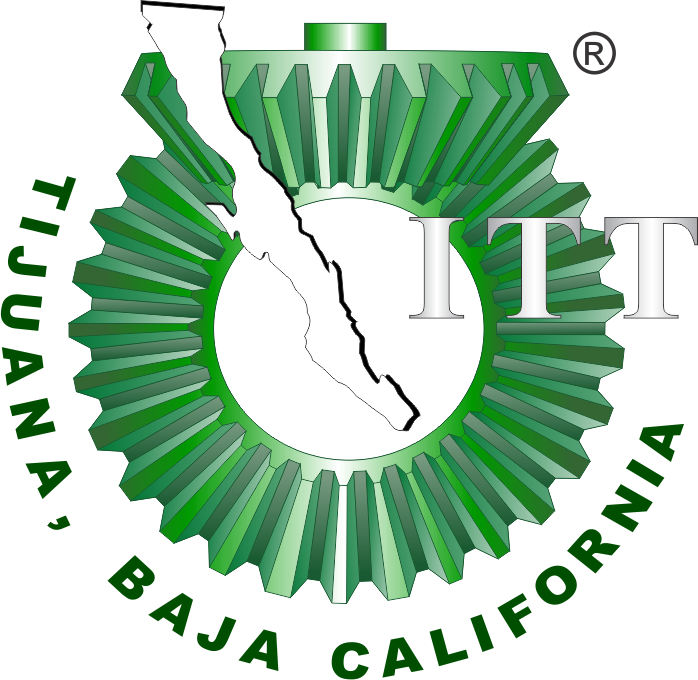

# Práctica 2: Sistema presa-depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

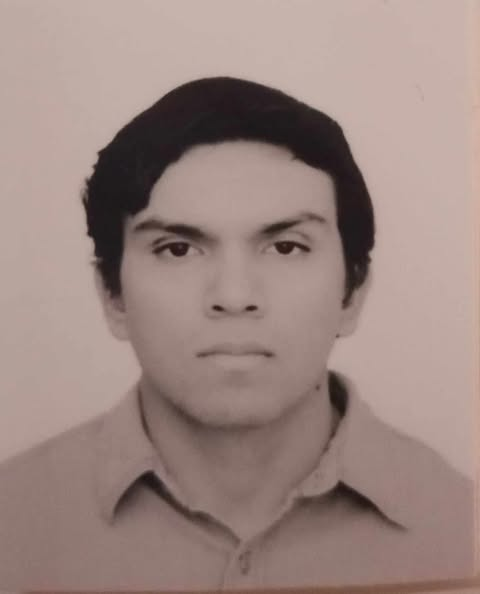

Nombre del alumno: **Chaparro Zamora Alain Yahir**

Número de control: **21212147**

Correo institucional: **l21212147@tectijuana.edu.mx**

**Carrera: Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetivo.** Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar si dinamica en series de tiempo y plano de fase. El sistema depredador se formula mediante las siguientes dos EDOs de primer orden.


$$\begin{array}{l}
\dot{x} =\alpha x-\beta \textrm{xy}\\
\dot{y} =\delta \textrm{xy}-\textrm{xy}
\end{array}$$


con los valores de los parametros $\alpha =0\ldotp 5,\beta =0\ldotp 01,\delta =0\ldotp 005\;y\;\gamma =0\ldotp 2$, y las condiciones iniciales x(0) = 0.75 y y(0) = 75.

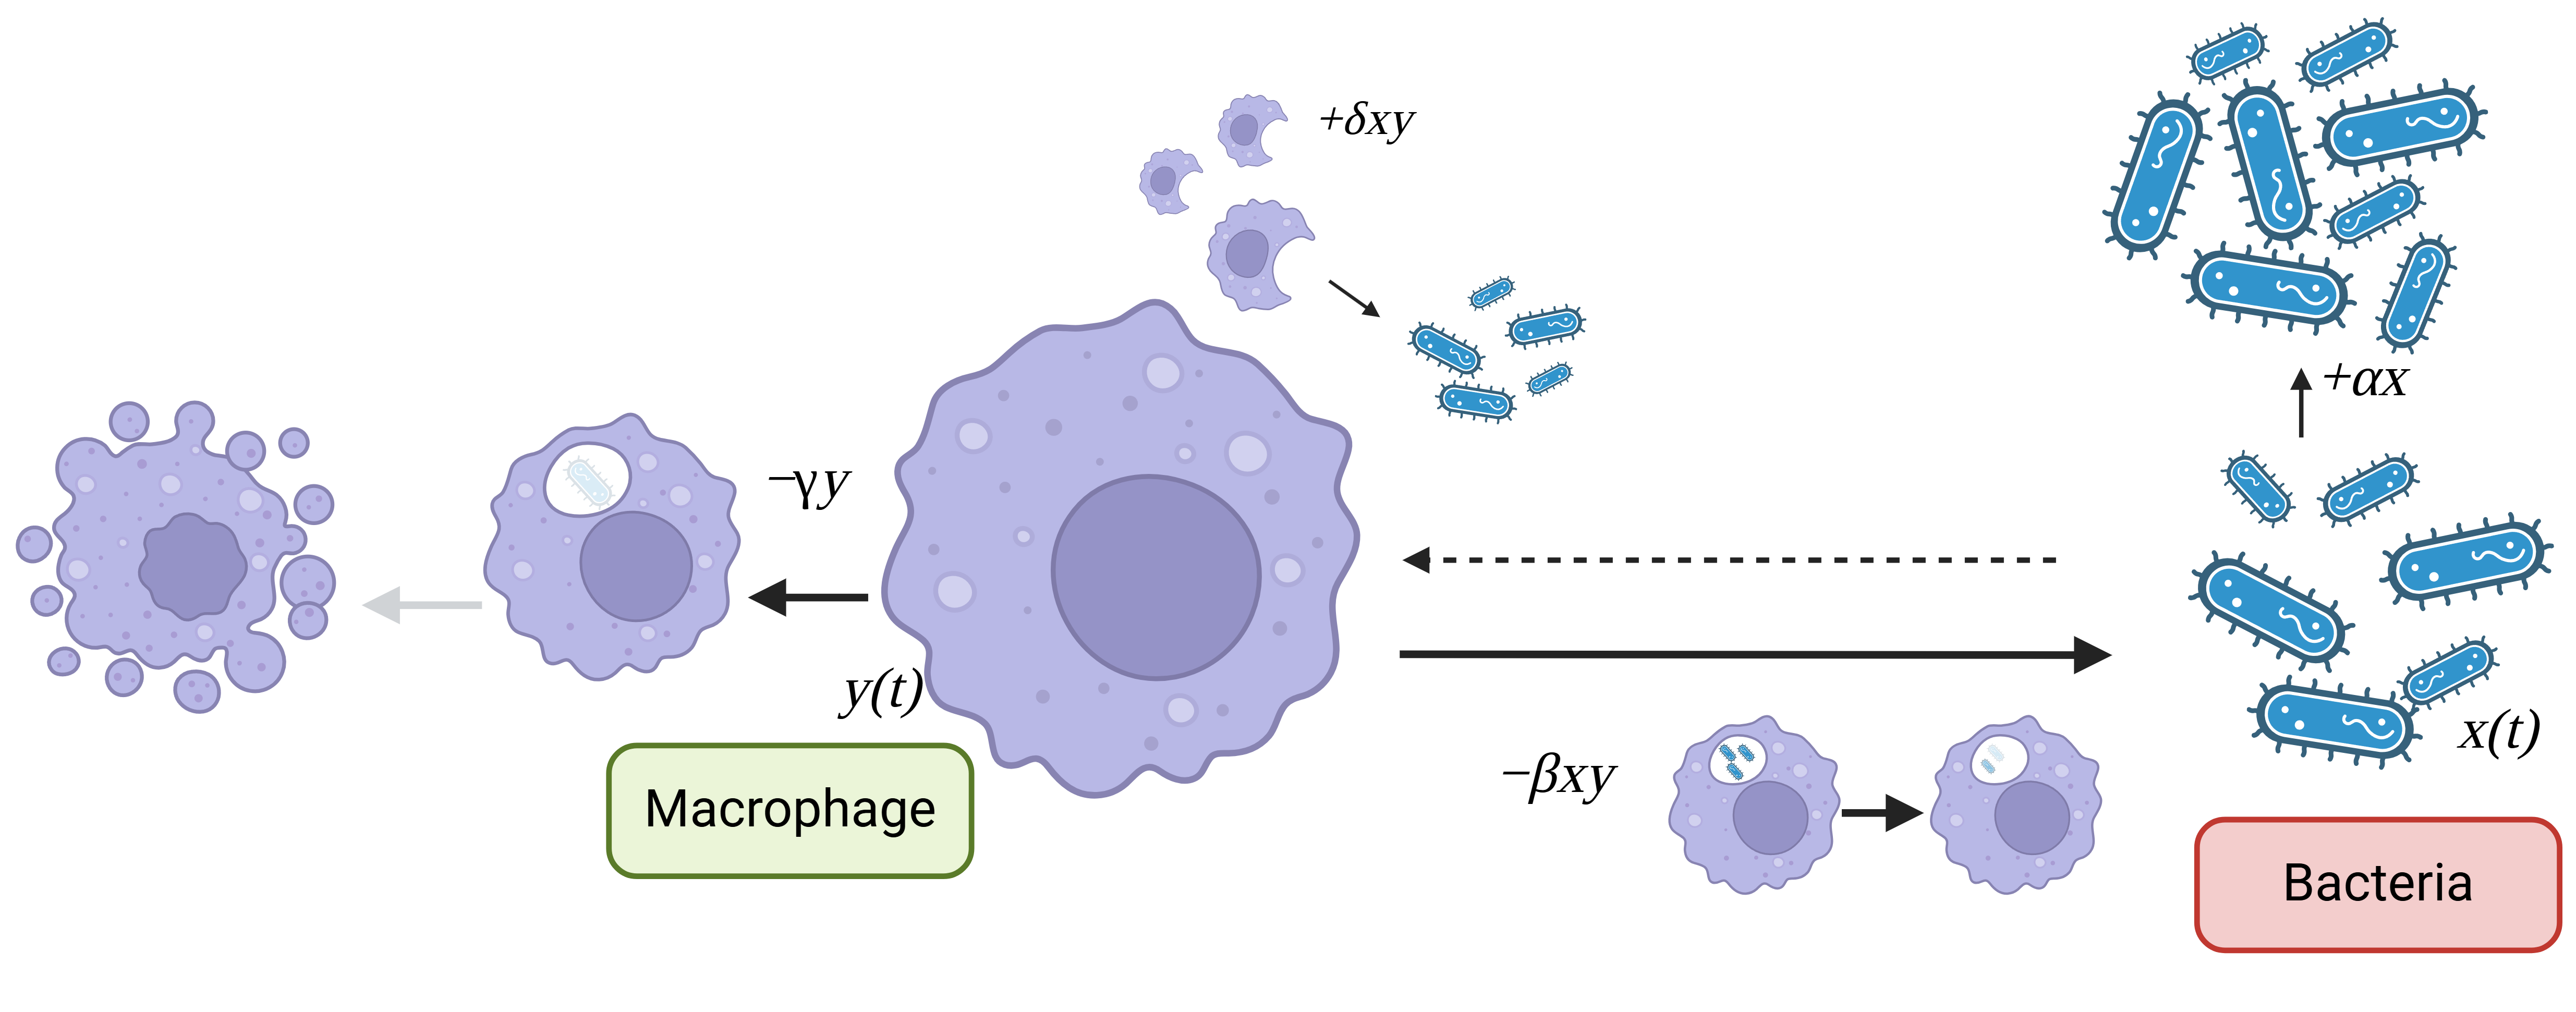

Figure. The **bacteria population** [x(t)] follows **exponential growth** [+αx] but is reduced by macrophages through **negative feedback** [−βxy], while the **macrophage population** [y(t)] experiences **exponential decay** [−γy] due to natural apoptosis but is stimulated by bacteria through **positive feedback** [+δxy]. 

## Simulation Data

clc; clear; close all; warning('off','all')

## Parameters and initial conditions

alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];
x0=75; y0=75; tend=100;

## Solution by Euler's method

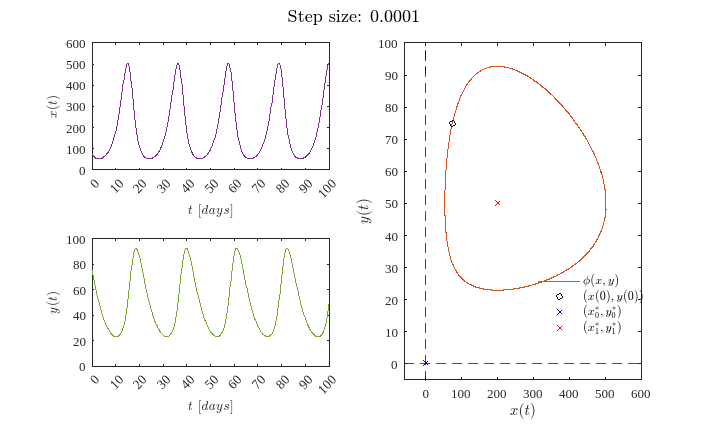

%dt = [2, 1, 0.5, 0.25, 1E-1, 1E-2, 1E-3, 1E-4, 1E-5, 1E-6];
dt=1E-4;
for i = 1:numel(dt)
    [t, x, y] = sys_Euler(x0, y0, dt(i), tend, P);  
    plotEDOs(t, x, y, P, dt(i))
    exportgraphics(gcf, ['Lotka-Volterra_Euler' num2str(dt(i)) '.PNG'], 'ContentType', 'vector')
end

## Solution by Heun's method

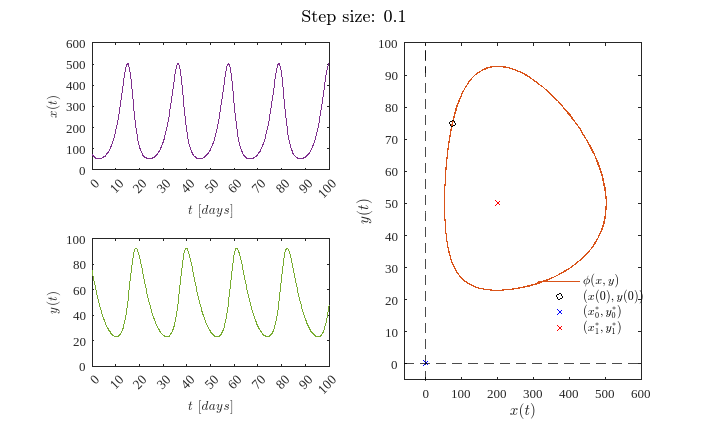

dt=1E-1;
for i = 1:numel(dt)
    [t, x, y] = sys_Heun(x0, y0, dt(i), tend, P);  
    plotEDOs(t, x, y, P, dt(i)) 
    exportgraphics(gcf, ['Lotka-Volterra_Heun' num2str(dt(i)) '.PNG'], 'ContentType', 'vector')
end

## Simulink

file = 'systemfeb';
sim(file);
parameters.StopTime = '100';
parameters.Solver = 'ode15s';

## Solution by Order15s 

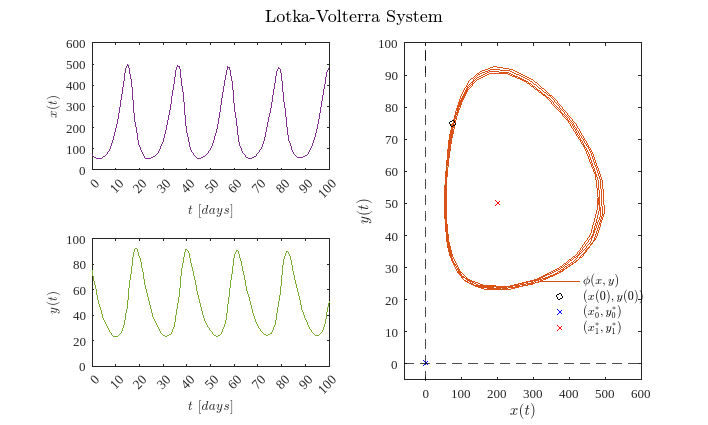

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode15s.pdf'],'ContentType','vector')

## Solution by Order23s 

parameters.Solver = 'ode23s'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode23s'


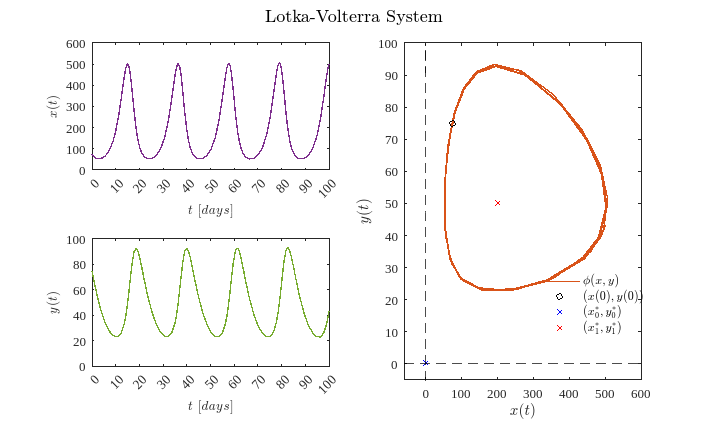

s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23s.pdf'],'ContentType','vector')

## Solution by Order23t 

parameters.Solver = 'ode23t'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode23t'


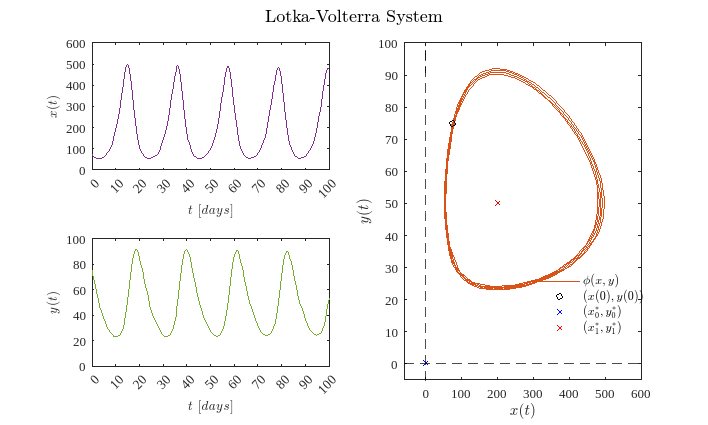

s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23t.pdf'],'ContentType','vector')

## Solution by Order23tb 

parameters.Solver = 'ode23tb'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode23tb'


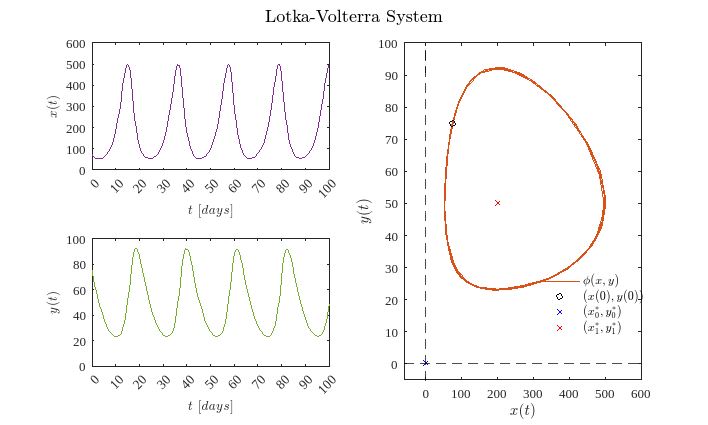

s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23tb.pdf'],'ContentType','vector')

## Solution by Order45

parameters.Solver = 'ode45'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode45'


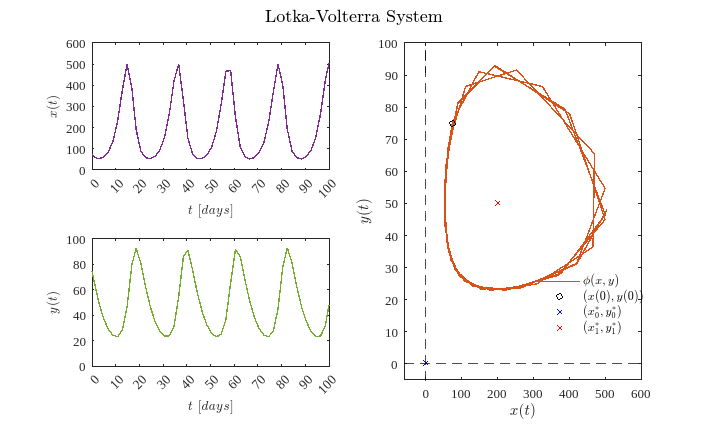

s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode45.pdf'],'ContentType','vector')

## Solution by Order23 

parameters.Solver = 'ode23'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode23'


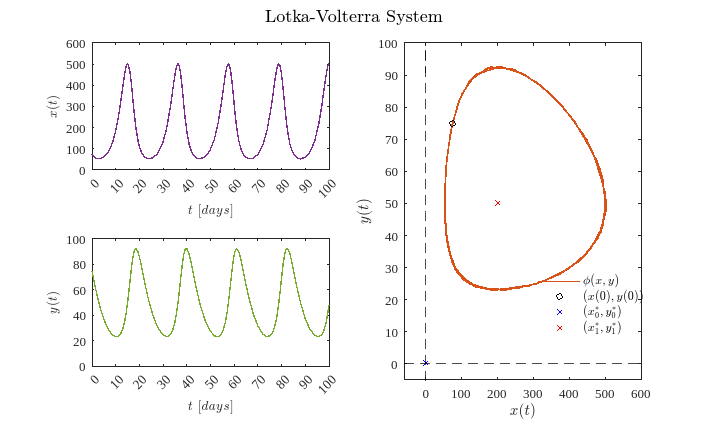

s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23.pdf'],'ContentType','vector')

## Solution by Order113 

parameters.Solver = 'ode113'

parameters = struct with fields:
    StopTime: '100'
      Solver: 'ode113'


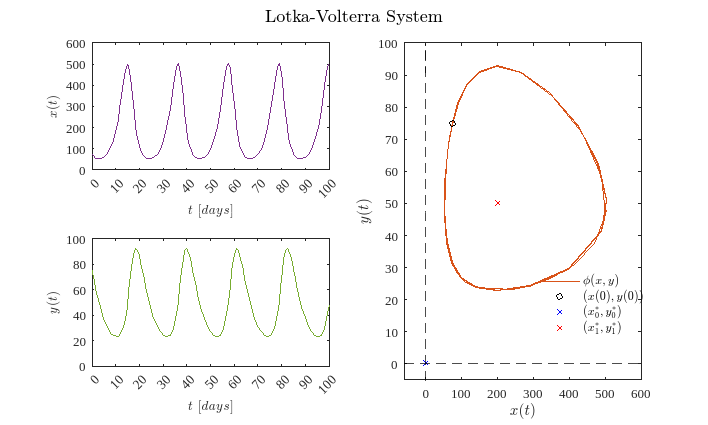

s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode113.pdf'],'ContentType','vector')

Con base en las simulaciones numéricas y en la teoría sobre ecuaciones diferenciales stiff y no stiff, ya que métodos explícitos muestran que el sistema se resuelve sin necesidad de pasos de tiempo muy pequeños, evitando mostrar múltiples escalas de tiempo las cuales son características de los sistemas stiff, por lo tanto se concluye que el sistema Lotka-Volterra no es stiff para los parámetros evaluados. 

[1] A. Garfinkel, J. Shevtsov, and Y. Guo, Modeling Life: The Mathematics of Biological Systems, 1st ed. Cham, Switzerland: Springer, 2017, ch. 1, sec. 1.1–1.3, pp. 1–18.[Consultado: 24-feb-2025].

[2]“Stiff Differential Equations”, Mathworks.com. [En línea]. Disponible en: https://www.mathworks.com/company/technical-articles/stiff-differential-equations.html. [Consultado: 24-feb-2025].

[3]“Determine System Stiffness”, Mathworks.com. [En línea]. Disponible en: https://www.mathworks.com/help/simscape/ug/determine-system-stiffness.html. [Consultado: 24-feb-2025].

## Equilibrium points

alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];
x0=75; y0=75; tend=100;
dt=1E-3;
    [t, x, y] = sys_Heun(x0, y0, dt, tend, P);
    plotEDOs(t, x, y, P, dt); ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Lotka-Volterra_Equilibria.pdf'], 'ContentType', 'vector')    

## Equilibirum Point and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx dy],[x y]);
fprintf('Jacobian matrix of the Lotka-Volterra system :'); disp(J)

Jacobian matrix of the Lotka-Volterra system :

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
Edos = solve([dx dy],[x y]);
fprintf(['The Lokta-Volterra system has  ', num2str(length(Edos.x)) , 'Equlibrium points.'])

The Lokta-Volterra system has  2Equlibrium points.

X0=Edos.x(1); Y0=Edos.y(1);
X1=Edos.x(2); Y1=Edos.y(2);
syms x0 x1 y0 y1
fprintf('Equilibrium Poins of the Lotka-Volterra system: ');...
    disp([x0 y0 X0 Y0]); disp([x1 y1 X1 Y1])

Equilibrium Poins of the Lotka-Volterra system: 

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear alpha beta delta gamma
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (',num2str(gamma/delta),',',num2str(alpha/beta),')']); 

(x0,y0) = (0,0)
(x1,y1) = (200,50)


## Local estability

clc; clear;
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
syms  x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1));
y0 = double(edos.y(1));
x1 = double(edos.x(2));
y1 = double(edos.y(2));
clear x y
x = [x0; x1]; 
y = [y0; y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium Poins of the Lotka-Volterra system: \n'); disp(Equilibria)

Equilibrium Poins of the Lotka-Volterra system: 
               xe     ye
               ___    __

    (x0,y0)      0     0
    (x1,y1)    200    50



L = zeros(length(x), length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i), -beta*x(i); 
         delta*y(i), delta*x(i) - gamma];

    L(i,:) = eig(J);
    disp(J)
end

    0.5000         0
         0   -0.2000

         0   -2.0000
    0.0500         0




L1 = L(:,1); 
L2 = L(:,2);

Lambdas = table(L1, L2, 'RowNames', var);

disp('Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:
                    L1               L2     
               _____________    ____________

    (x0,y0)    -0.2+0i          0.5+0i      
    (x1,y1)       0+0.31623i      0-0.31623i



Los casos marginales, como los centros, no pueden clasificarse directamente como estables o inestables usando la teoría lineal, ya que sus valores propios tienen parte real igual a cero . En estos casos, las trayectorias pueden ser cerradas o evolucionar de manera más compleja dependiendo de términos no lineales. Esto los convierte en casos marginales, porque la estabilidad no puede determinarse solo con los autovalores de la matriz Jacobiana, sino que requiere un análisis más profundo, como el uso de funciones de Lyapunov o expansión en términos de orden superior.

## Data fitting

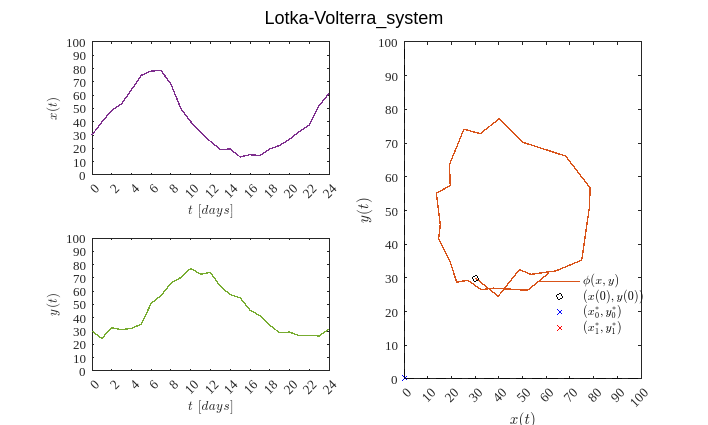

clc; clear; close all;

sys = readmatrix('data.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];

  plotEDOsx(to, xo, yo, P, 0);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data Fitting Lotka-Volterra.pdf'], 'ContentType', 'vector')

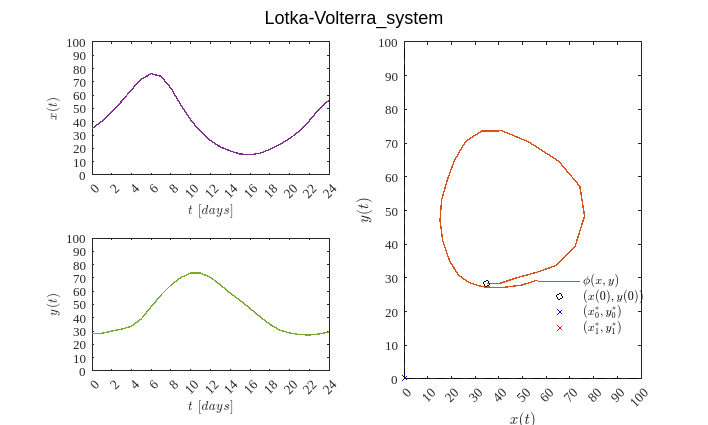

       
        xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
  plotEDOsx(to, xo, yo, P, 0);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data Fitting Lotka-Volterra (Smooth).pdf'], 'ContentType', 'vector')

### Fit data

P0 = [1;0.001;0.001;0.1];
mdl = Variant(to,xo,yo,P0);

t-Studen value: 2.0129
 

Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
-Student value: 2.0129
Adjusted R-squared: 0.9916
Corrected AIC (n/pars<40) : 198.5775
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42255     0.0077033      0.015506      0.40704      0.43806    1.4454e-43
      beta        0.0088734    0.00019132    0.00038511    0.0084883    0.0092585    2.8424e-40
      delta       0.0052888    0.00011174    0.00022493    0.0050639    0.0055137     1.139e-40
      gamma         0.21734     0.0047267     0.0095144      0.20783      0.22686    4.18

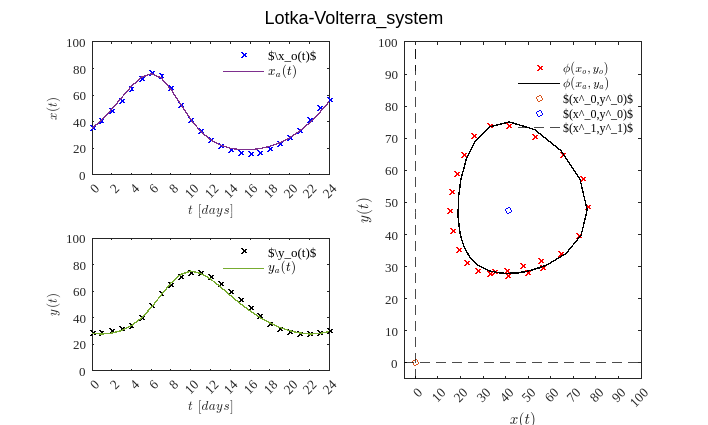

fa=mdl.Fitted;
fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data FIT.pdf'], 'ContentType', 'vector')

## Experimental data for "  Macro-Bacteria  "

clc; clear; close all;

### Raw Data Macro-Bacteria

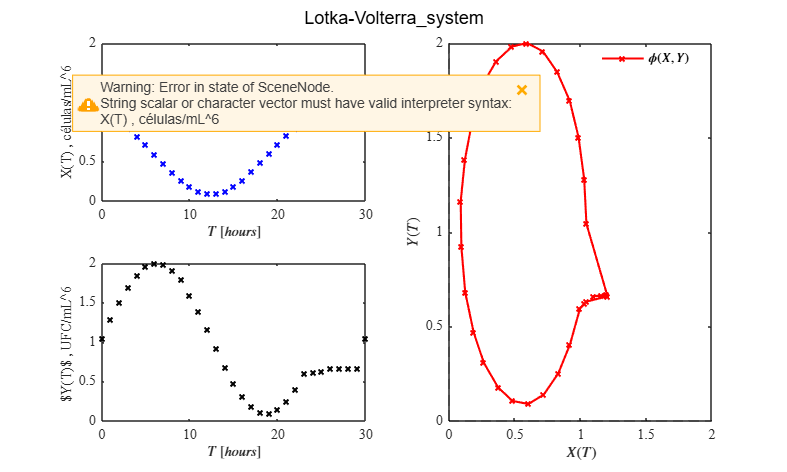

sys = readmatrix('datosX.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];

  plotX(to, xo, yo, P, 0);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data Fitting Lotka-Volterra.pdf'], 'ContentType', 'vector')

### Smooth data Macro-Bacteria

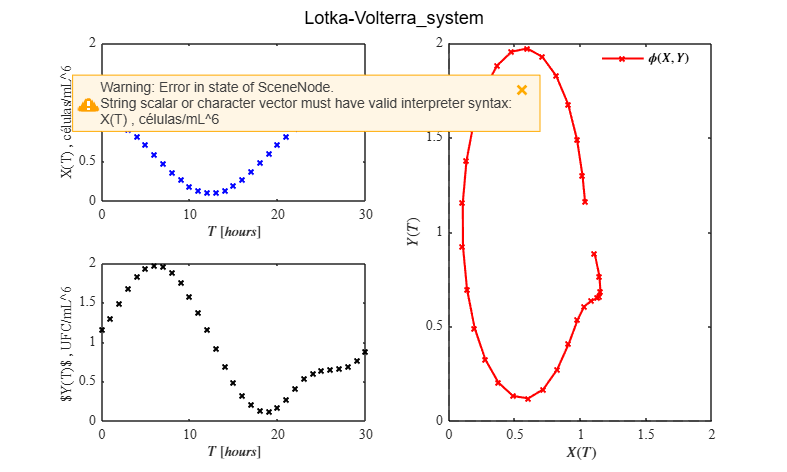

    xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
  plotX(to, xo, yo, P, 0);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data Fitting Lotka-Volterra (Smooth).pdf'], 'ContentType', 'vector')

### Fit data Macro-Bacteria

P0 = [2;0.001;0.001;0.1];
mdl = Variant(to,xo,yo,P0);fa=mdl.Fitted;

t-Studen value: 2.0017
 

Sample size (n): 31
Parameters to be estimated (pars): 4
Degrees of freedom: 58
Significance level (alpha): 0.05
-Student value: 2.0017
Adjusted R-squared: 0.8852
Corrected AIC (n/pars<40) : -32.5805
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      alpha       0.13828     0.017384    0.034797    0.10348    0.17308    7.2958e-11
      beta        0.13661     0.016623    0.033274    0.10333    0.16988    2.6423e-11
      delta       0.51742     0.043742    0.087558    0.42986    0.60498    4.2824e-17
      gamma       0.33525     0.039923    0.079915    0.25534    0.41517     1.326e-11



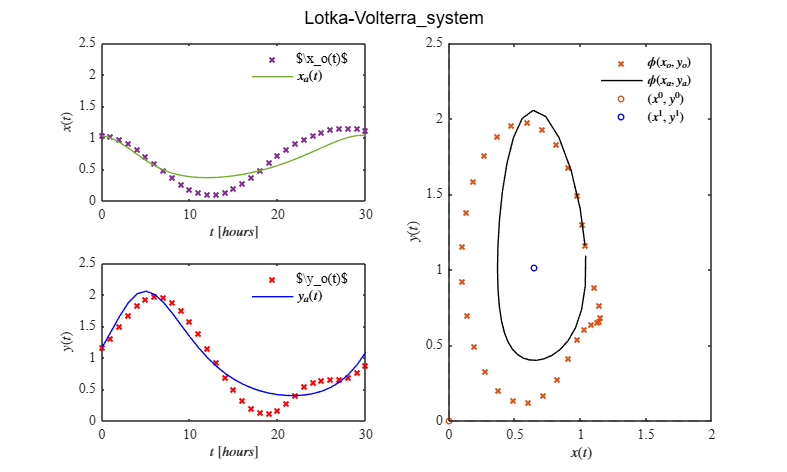

fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
fa=mdl.Fitted;
fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
plotY(to,[xo,xa],[yo,ya],P);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data FIT.pdf'], 'ContentType', 'vector')    

## Functions

## Euler's method

function [t, x, y] = sys_Euler(x0, y0, dt, tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)';
    
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i)+dt*(alpha*x(i)-beta*x(i)*y(i));
        y(i+1) = y(i)+dt*(delta*x(i)*y(i)-gamma*y(i));
    end
end

## Heun's method

function [t,x,y] = sys_Heun(x0,y0,dt,tend,P)
 alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
 n = round(tend/dt);
 t = (0:dt:tend);
 x = zeros(length(t),1); x(1) = x0;
 y = zeros(length(t),1); y(1) = y0;

 for i = 1:n
    [fx,fy] = f(x(i),y(i));
    xn = x(i) + fx*dt;
    yn = y(i) + fy*dt;
    [fxn,fyn] = f(xn,yn);

    x(i+1) = x(i) + (fx + fxn)*dt/2;
    y(i+1) = y(i) + (fy + fyn)*dt/2;
 end

    function [dx,dy] = f(x,y)
    dx = alpha*x-beta*x*y;
    dy = delta*x*y-gamma*y;
    end
end

## Solutions and trajectories

function plotEDOs(t,x,y,P,dt)
    morado = [0.4940 0.1840 0.5560]; 
    verde = [0.4660 0.6740 0.1880]; 
    rosa = [0.8500 0.3250 0.0980]; 
    negro = [0 0 0];     
    rojo  = [1 0 0];     
    azul = [0 0 1];
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',morado)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',verde)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
   xlim([0 100]); xticks(0:10:100)
   ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off
    plot(x,y,'-','LineWidth',1,'Color',rosa)
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1,'Color',negro)
    plot(0,0,'x','MarkerSize',5,'LineWidth',1,'Color',azul)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',rojo)
    xlabel('$x(t)$', 'Interpreter','latex')
    ylabel('$y(t)$', 'Interpreter','latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$', '$(x(0),y(0))$', '$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'none', 'Position', [0.778, 0.263, 0.115, 0.041], 'Box', 'Off')
if dt == 0
        ttl = ['Lotka-Volterra System'];
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
end
end

function plotEDOsx(t,x,y,P,dt)
    morado = [0.4940 0.1840 0.5560]; 
    verde = [0.4660 0.6740 0.1880]; 
    rosa = [0.8500 0.3250 0.0980]; 
    negro = [0 0 0];     
    rojo  = [1 0 0];     
    azul = [0 0 1];
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',morado)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:10:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',verde)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:10:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off
    plot(x,y,'-','LineWidth',1,'Color',rosa)
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1,'Color',negro)
    plot(0,0,'x','MarkerSize',5,'LineWidth',1,'Color',azul)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',rojo)
    xlabel('$x(t)$', 'Interpreter','latex')
    ylabel('$y(t)$', 'Interpreter','latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$', '$(x(0),y(0))$', '$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'none', 'Position', [0.778, 0.263, 0.115, 0.041], 'Box', 'Off')
if dt == 0
        ttl = ['Lotka-Volterra System'];
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
end
end

## Nonlinear regression algorithm


function mdl= Variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy = delta*x*y-gamma*y;
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha=0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['t-Studen value: ',num2str(tval)])
    disp(' ')
    
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(P0))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end
%VariantX
function mdl = Variantx(to, xo, yo, P0)
    x0 = xo(1);
    y0 = yo(1);
    to = to(:); % Asegurar que sea un vector columna
    fo = xo(:); % Ajustar para que tenga la misma longitud que to

    function xi = model(p, t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = t(:); % Asegurar que t sea un vector columna
        time = (0:dt:max(t))';
        n = length(time);
        
        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        
        for i = 1:n-1
            [fx, fy] = f(x(i), y(i));
            xn = x(i) + fx * dt;
            yn = y(i) + fy * dt;
            [fxn, fyn] = f(xn, yn);
            x(i+1) = x(i) + (fx + fxn) * dt / 2;
            y(i+1) = y(i) + (fy + fyn) * dt / 2;
        end
        
        function [dx, dy] = f(x, y)
            dx = alpha * x - beta * x * y;
            dy = delta * x * y - gamma * y;
        end 
        
        xi = zeros(length(t), 1);
        for j = 1:length(t)
            [~, k] = min(abs(time - t(j))); % Encontrar el índice más cercano
            xi(j) = x(k); % Solo usamos x para ajustarlo con fo
        end
    end
    
    mdl = fitnlm(to, fo, @model, P0);
    
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE; 
    tval = tinv(1 - alpha / 2, dof);
    MoE = SE * tval;
    Parameters = ['alpha'; 'beta '; 'delta'; 'gamma'];
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    
    disp(['t-Student value: ', num2str(tval)])
    disp(' ')
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(P0))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end

function plotResults(t,x,y,P,dt)
  morado = [0.4940 0.1840 0.5560]; 
    verde = [0.4660 0.6740 0.1880]; 
    rosa = [0.8500 0.3250 0.0980]; 
    negro = [0 0 0];     
    rojo  = [1 0 0];     
    azul = [0 0 1];
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',azul)
    plot(t,x(:,2),'-','LineWidth',1,'Color',morado)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)
    L = legend('$\x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',negro)
    plot(t,y(:,2),'-','LineWidth',1,'Color',verde)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)
    L = legend('$\y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

  subplot(2,2,[2 4])
set(gca,'FontName','Times New Roman'); fontsize(10,'points')
hold on; box on; grid off;
plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',rojo) 
plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',negro) 
plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',rosa) 
plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',azul)

xlabel('$x(t)$','Interpreter','latex')
ylabel('$y(t)$','Interpreter','latex')

xlim([-5 100]); xticks(0:10:100)
ylim([-5 100]); yticks(0:10:100)

xline(0,'--','LineWidth',1,'Color','k')
yline(0,'--','LineWidth',1,'Color','k')

L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^_0,y^_0)$','$(x^_0,y^_0)$','$(x^_1,y^_1)$');
set(L,'Interpreter','latex','Location','Best','Box','Off')

    
end

function plotX(T,X,Y,P,dt)
  morado = [0.4940 0.1840 0.5560]; 
  verde = [0.4660 0.6740 0.1880]; 
  rosa = [0.8500 0.3250 0.0980]; 
  negro = [0 0 0];     
  rojo  = [1 0 0];     
  azul = [0 0 1];
  
  set(figure(),'Color','w')
  set(gcf,'Units','Centimeters','Position',[2,2,20,12])
  alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

  % Subplot 1: Macrófagos vs Tiempo
  subplot(2,2,1)
  set(gca,'FontName','Times New Roman'); fontsize(10,'points');
  hold on; box on; grid off;
  plot(T,X,'x','MarkerSize',5,'LineWidth',1.5,'Color',azul)
  xlabel('$T$ $[hours]$','Interpreter','Latex')
 %  ylabel('$X(T)$ (Macrófagos, células/mL^6)','Interpreter','Latex')
ylabel('X(T) , células/mL^6', 'Interpreter', 'latex')

  xlim([0 30])                     
  ylim([0 2])                    
  xticks(0:10:30)                
  yticks(0:0.5:2)              

  % Subplot 3: Bacterias vs Tiempo
  subplot(2,2,3)
  set(gca,'FontName','Times New Roman'); fontsize(10,'points');
  hold on; box on; grid off;
  plot(T,Y,'x','MarkerSize',5,'LineWidth',1.5,'Color',negro)
  xlabel('$T$ $[hours]$','Interpreter','Latex')
  ylabel('$Y(T)$ , UFC/mL^6 ','Interpreter','Latex')
  xlim([0 30])                    
  ylim([0 2])                   
  xticks(0:10:30)              
  yticks(0:0.5:2)               

  % Subplot 2+4: Diagrama de fase
  subplot(2,2,[2 4])
  set(gca,'FontName','Times New Roman'); fontsize(10,'points')
  hold on; box on; grid off;
  plot(X,Y,'x-','MarkerSize',5,'LineWidth',1.5,'Color',rojo) 
  xlabel('$X(T)$','Interpreter','latex')
  ylabel('$Y(T)$','Interpreter','latex')
  xlim([0 2])                   
  ylim([0 2])                   
  xticks(0:0.5:2)               
  yticks(0:0.5:2)            

  % Líneas de referencia
  xline(0,'--','LineWidth',1,'Color','k')
  yline(0,'--','LineWidth',1,'Color','k')

  L = legend ('$\phi(X,Y)$');
  set(L,'Interpreter','latex','Location','Best','Box','Off')
end

%PlotY
function plotY(t,x,y,P,dt)
 morado = [0.4940 0.1840 0.5560]; 
  verde = [0.4660 0.6740 0.1880]; 
  rosa = [0.8500 0.3250 0.0980]; 
  negro = [0 0 0];     
  rojo  = [1 0 0];     
  azul = [0 0 1];
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);


 subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',morado)
    plot(t,x(:,2),'-','LineWidth',1,'Color',verde)
    xlabel('$t$ $[hours]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
  xlim([0 30])                    
  ylim([0 2.5])                   
  xticks(0:10:30)              
  yticks(0:0.5:2.5)    
    L = legend('$\x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',rojo)
    plot(t,y(:,2),'-','LineWidth',1,'Color',azul)
    xlabel('$t$ $[hours]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
xlim([0 30])                    
  ylim([0 2.5])                   
  xticks(0:10:30)              
  yticks(0:0.5:2.5)    
    L = legend('$\y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',rosa) 
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',negro) 
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',rosa) 
    plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',azul)

    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')

  xlim([0 2])                   
  ylim([0 2.5])                   
  xticks(0:0.5:2)               
  yticks(0:0.5:2.5) 

    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^0,y^0)$','$(x^1,y^1)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
end
